% Load the model we have derived from the inversion (only for the ice shelf
% -- which means the mds model)
cd '/Users/rishi/Desktop/ISSM-macOS-Silicon-MATLAB/examples/Pig/Models'
md = loadmodel('Ross_Inversion_Bedmachine.mat')

md =                mesh: [1x1 mesh2d]            -- mesh properties
               mask: [1x1 mask]              -- defines grounded and floating elements
           geometry: [1x1 geometry]          -- surface elevation, bedrock topography, ice thickness,...
          constants: [1x1 constants]         -- physical constants
                smb: [1x1 SMBforcing]        -- surface mass balance
      basalforcings: [1x1 basalforcings]     -- bed forcings
          materials: [1x1 matice]            -- material properties
             damage: [1x1 damage]            -- parameters for damage evolution solution
           friction: [1x1 friction]          -- basal friction/drag properties
       flowequation: [1x1 flowequation]      -- flow equations
       timestepping: [1x1 timestepping]      -- time stepping for transient models
     initialization: [1x1 initialization]    -- initial guess/state
              rifts: [1x1 rifts]             -- rifts properties
         solidearth: [1x1 s

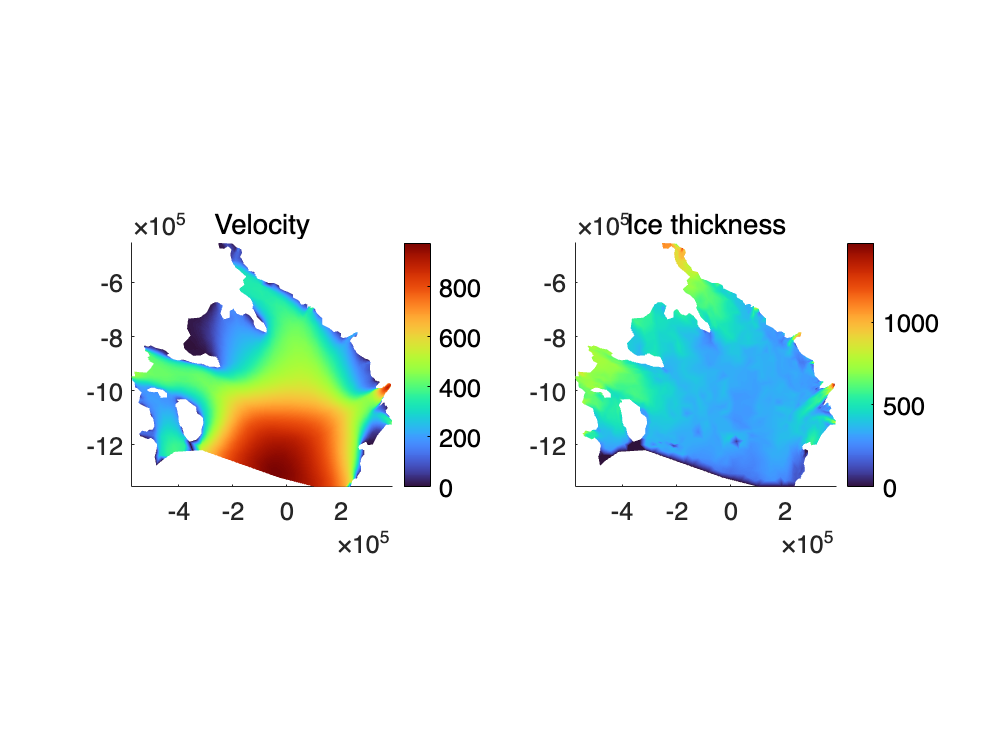

% plot a data and check whether the data is properly imported
plotmodel(md,'data',md.results.StressbalanceSolution.Vel,'title','Velocity','colormap','turbo', ...
            'data',md.geometry.thickness,'title','Ice thickness','colormap','turbo')

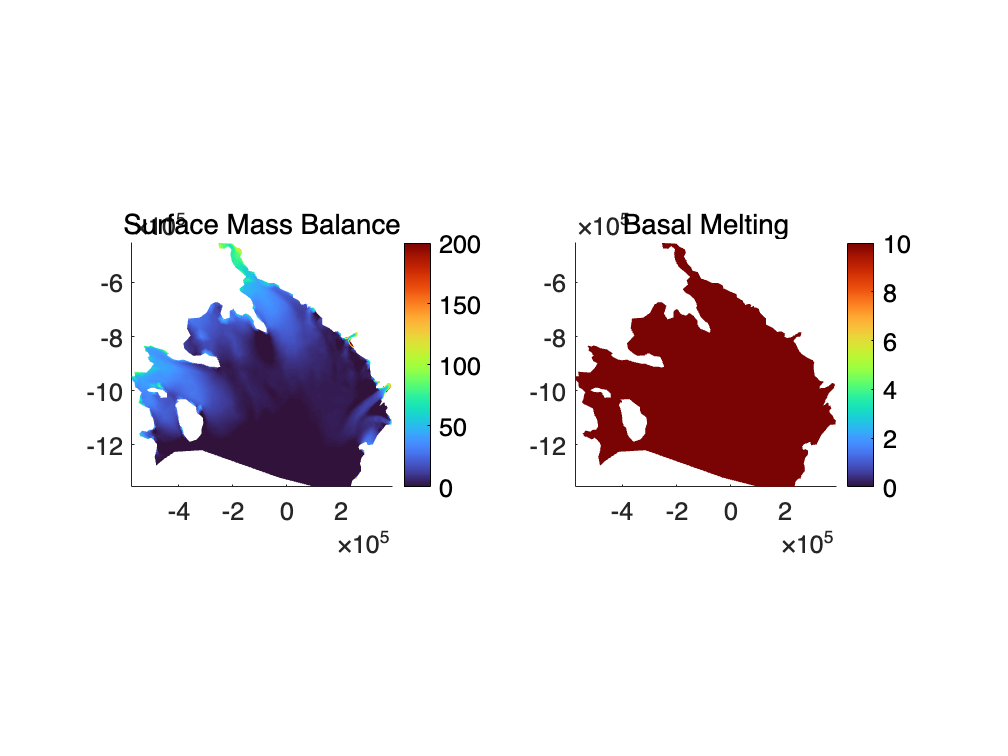

% reinitialize the ice level set for the shelf
md.mask.ice_levelset = reinitializelevelset (md,md.mask.ice_levelset);

%Apply basal melt conditions
md.basalforcings.groundedice_melting_rate = zeros(md.mesh.numberofvertices,1);
md.basalforcings.floatingice_melting_rate = 25*ones(md.mesh.numberofvertices,1);

%Apply surface mass balance conditions
searise='/Users/rishi/Desktop/ISSM-macOS-Silicon-MATLAB/examples/Data/Antarctica_5km_withshelves_v0.75.nc';

smb   = ncread(searise,'presprcp')'; % surface mass balance - precipitation data
x1=double(ncread(searise,'x1')); 
y1=double(ncread(searise,'y1'));
surface = double(ncread(searise,'usrf'));
basal_melt = double(ncread(searise,'melt'));

% apply surface and basal melt focing on the model for the transient run
md.smb.mass_balance = double(InterpFromGridToMesh(x1,y1,surface',md.mesh.x,md.mesh.y,0));
%md.basalforcings.floatingice_melting_rate = double(InterpFromGridToMesh(x1,y1,basal_melt',md.mesh.x,md.mesh.y,0));

%check whether the surface mass baalance is properly implemented
plotmodel(md,'data',md.smb.mass_balance,'title','Surface Mass Balance','caxis#1',[0 200],...
    'data',md.basalforcings.floatingice_melting_rate,'title','Basal Melting','caxis#2',[0 10])

%Indicate the components of transient to activate
md.transient.ismasstransport = 1;
md.transient.isstressbalance = 1;
md.transient.isgroundingline = 1;
md.transient.ismovingfront = 0;
md.transient.isthermal = 0;

%Specify time steps and length of simulation (years)
md.timestepping.start_time = 0;
md.timestepping.time_step = 0.1;
md.timestepping.final_time = 10;

%Disable inverse method
md.inversion.iscontrol=0;

%Initialize fields for transient and add boundary conditions
md.initialization.vx = md.results.StressbalanceSolution.Vx;
md.initialization.vy = md.results.StressbalanceSolution.Vy;
md.initialization.vel = md.results.StressbalanceSolution.Vel;
md.masstransport.spcthickness = NaN*ones(md.mesh.numberofvertices,1);

%Request additional outputs
md.transient.requested_outputs={'default','IceVolume','IceVolumeAboveFloatation','TotalSmb','TotalFloatingBmb'};

%Solve transient solution and change messages provided
md.verbose = verbose('solution',false);
md=solve(md,'Transient');

launching solution sequence
hostname contains invalid characters
ssh -l  debangshusmacbookpro.local "source  Ross_Inversion.queue ": Signal 127


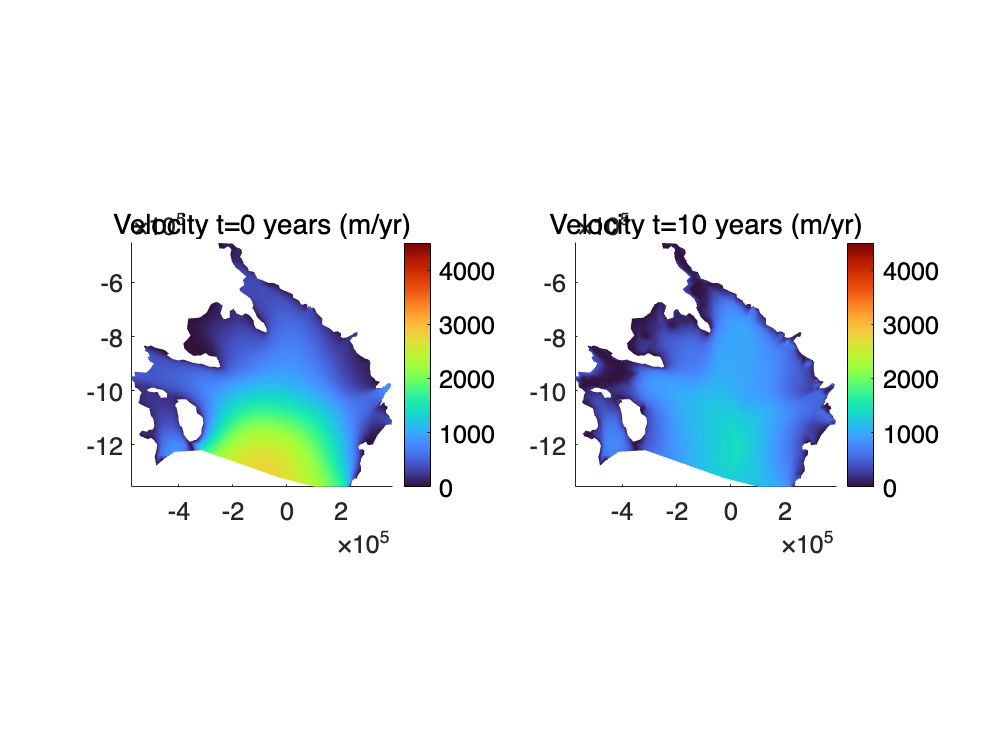

%Plot results
plotmodel(md, 'data', md.results.TransientSolution(1).Vel,'title#1', 'Velocity t=0 years (m/yr)',...
  'data', md.results.TransientSolution(end).Vel,'title#2', 'Velocity t=10 years (m/yr)',...
  'caxis#1',([0 4500]),'caxis#2',([0 4500]));

%Change basal melt rate
md.basalforcings.groundedice_melting_rate = zeros(md.mesh.numberofvertices,1);
md.basalforcings.floatingice_melting_rate = 10*ones(md.mesh.numberofvertices,1);

%Solve transient solution
md.verbose = verbose('solution',false);
md = solve(md,'Transient');

launching solution sequence

Ice-sheet and Sea-level System Model (ISSM) version  4.24
(website: http://issm.jpl.nasa.gov forum: https://issm.ess.uci.edu/forum/)

call computational core:
write lock file:

   FemModel initialization elapsed time:   0.012221
   Total Core solution elapsed time:       17.6102
   Linear solver elapsed time:             13.9218 (79%)

   Total elapsed time: 0 hrs 0 min 17 sec


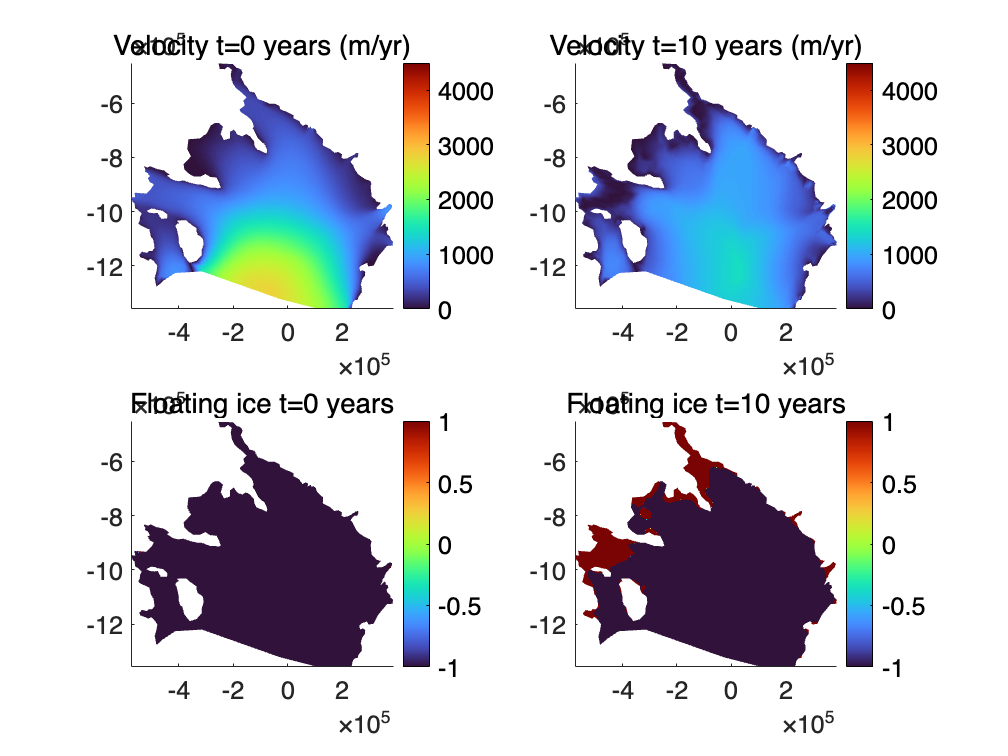

%Plot results
plotmodel(md, 'data', md.results.TransientSolution(1).Vel,'title#1', 'Velocity t=0 years (m/yr)',...
  'data', md.results.TransientSolution(end).Vel,'title#2', 'Velocity t=10 years (m/yr)',...
  'data', md.results.TransientSolution(1).MaskOceanLevelset,'title#3', 'Floating ice t=0 years',...
  'data', md.results.TransientSolution(end).MaskOceanLevelset,'title#4', 'Floating ice t=10 years',...
  'caxis#1',([0 4500]),'caxis#2',([0 4500]),'caxis#3',([-1,1]),'caxis#4',([-1,1]));

% try to produce the mechanical properties of an ice shelf from the
% transient run

% This is the stress and strain output of the first year before run
vx1 = md.results.TransientSolution(1).Vx;
vy1 = md.results.TransientSolution(1).Vy;
md = mechanicalproperties(md, vx1, vy1);
md.results.deviatoricstress_start = md.results.deviatoricstress;

% This is the stress and strain output of the end year after run
vxt = md.results.TransientSolution(end).Vx;
vyt = md.results.TransientSolution(end).Vy;
md = mechanicalproperties(md, vxt, vyt);
md.results.deviatoricstress_end = md.results.deviatoricstress;

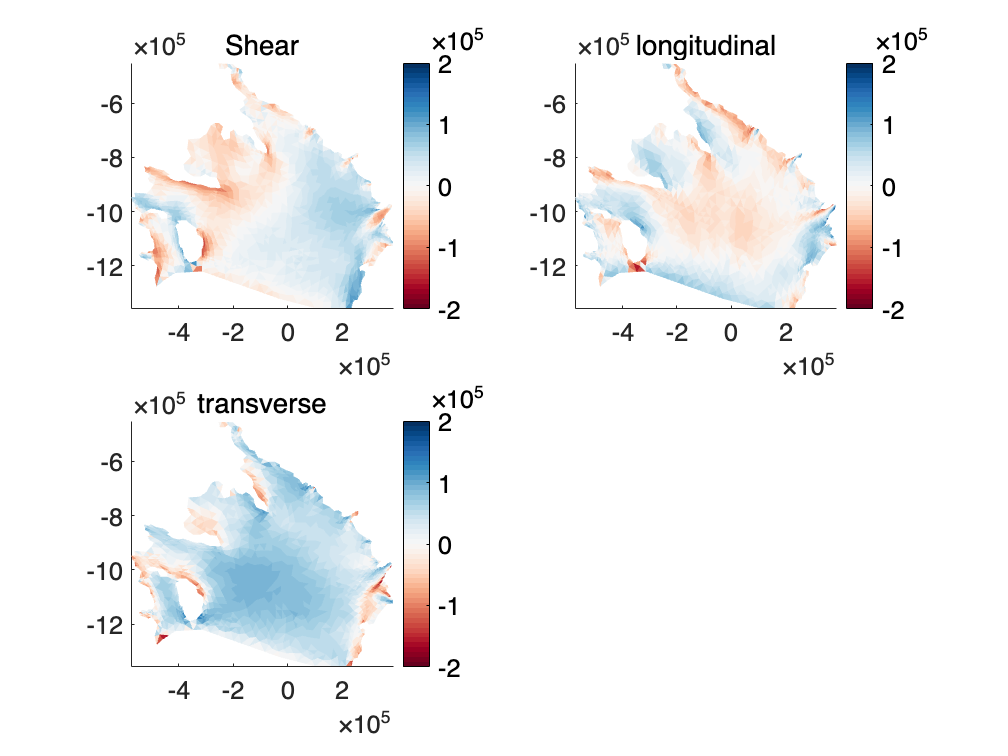

% plotting the Deviatoric Stresses
plotmodel(md,'data',md.results.deviatoricstress_start.xy,'title','Shear',...
'data',md.results.deviatoricstress_start.xx,'title','longitudinal',...
'data',md.results.deviatoricstress_start.yy,'title','transverse','caxis#all',[-2e5 2e5]);
colormap(brewermap(50, 'RdBu'));

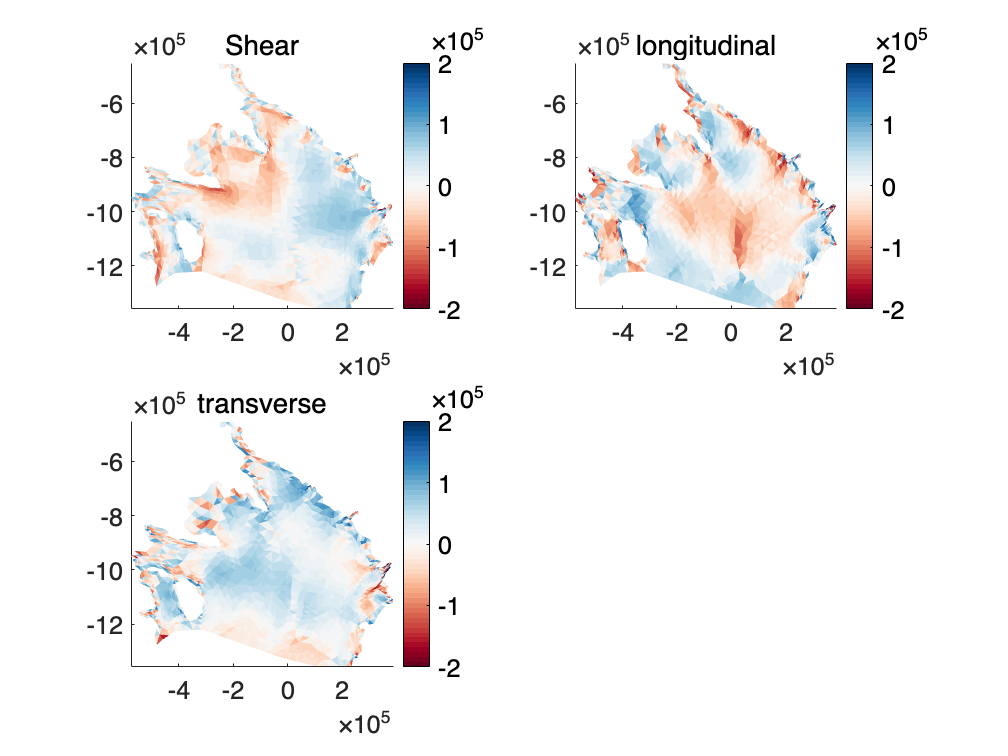

% plotting the Deviatoric Stresses for the last year
plotmodel(md,'data',md.results.deviatoricstress_end.xy,'title','Shear',...
'data',md.results.deviatoricstress_end.xx,'title','longitudinal',...
'data',md.results.deviatoricstress_end.yy,'title','transverse','caxis#all',[-2e5 2e5]);
colormap(brewermap(50, 'RdBu'));